# Ejercicios de la Memoria del Laboratorio.

**Jesús María Mora Mur**

% Representar las siguientes funciones
% Estudiar su continuidad, derivadas parciales y cualquier aspecto que
% podrías indicar reseñable respecto a la diferenciabilidad de las mismas.


% f(x,y)=x^2/(x^2+y^2)  (x,y)!=0
% f(x,y)=0              (x,y)=(0,0)
% Dominio -1<x<1 -1<y<1

% f(x,y)=2*x*y/(x^2+y^2)  (x,y)!=(0,0) 
% f(x,y)=0                (x,y)=(0,0)
% Dominio -1<x<1 -1<y<1

## Primera función.

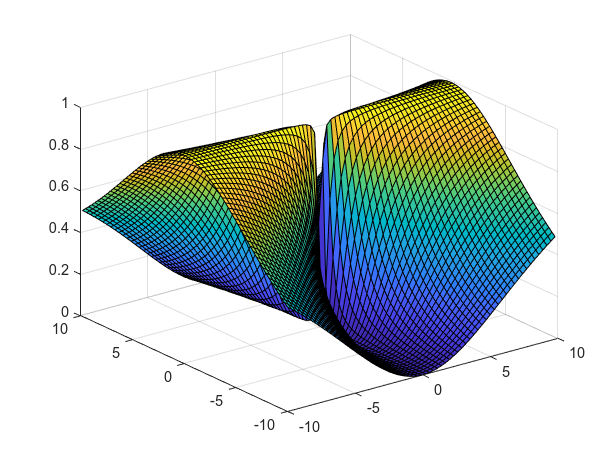

[x,y] = meshgrid(-10:0.3:10,-10:0.3:10);
v= x.*x./(x.^2 + y.^2); % Con x.^2 en el numerador no funciona. ¿Por qué será?
surf(x,y,v)

syms x y
g(x,y) = x^2/(x^2 + y^2)

$$g(x, y) = \frac{x^{2}}{x^{2}+y^{2}}$$

Parece que en **(0,0)** hay problemas para representar. Lo vemos también al sustituir. Comprobamos con límites:

### Límites. Continuidad.

limit(limit(g(x,y),x,0),y,0)

$$ans = 0$$

limit(limit(g(x,y),y,0),x,0)

$$ans = 1$$

Como salen diferentes se ve claramente que la función no es continua ni diferenciable en `(x,y) = (0,0)`. Si se restringe ese punto, la función es continua y diferenciable.

### Derivadas parciales.

g = x^2/(x^2 + y^2)

$$g = \frac{x^{2}}{x^{2}+y^{2}}$$

g1x = diff(g,x,1)

$$g1x = \frac{2\,x}{x^{2}+y^{2}}-\frac{2\,x^{3}}{{\left(x^{2}+y^{2}\right)}^{2}}$$

g1y = diff(g,y,1)

$$g1y = -\frac{2\,x^{2}\,y}{{\left(x^{2}+y^{2}\right)}^{2}}$$

g2xy = diff(g1x,y)

$$g2xy = \frac{8\,x^{3}\,y}{{\left(x^{2}+y^{2}\right)}^{3}}-\frac{4\,x\,y}{{\left(x^{2}+y^{2}\right)}^{2}}$$

g2yx = diff(g1y,x)

$$g2yx = \frac{8\,x^{3}\,y}{{\left(x^{2}+y^{2}\right)}^{3}}-\frac{4\,x\,y}{{\left(x^{2}+y^{2}\right)}^{2}}$$

g2x = diff(g,x,2)

$$g2x = \frac{2}{x^{2}+y^{2}}-\frac{10\,x^{2}}{{\left(x^{2}+y^{2}\right)}^{2}}+\frac{8\,x^{4}}{{\left(x^{2}+y^{2}\right)}^{3}}$$

g2y = diff(g,y,2)

$$g2y = \frac{8\,x^{2}\,y^{2}}{{\left(x^{2}+y^{2}\right)}^{3}}-\frac{2\,x^{2}}{{\left(x^{2}+y^{2}\right)}^{2}}$$

#### Matrices Jacobiana y Hessiana.

jacobiana_g = jacobian(g)

$$jacobiana\_g = \left(\begin{array}{cc} \frac{2\,x}{x^{2}+y^{2}}-\frac{2\,x^{3}}{{\left(x^{2}+y^{2}\right)}^{2}} & -\frac{2\,x^{2}\,y}{{\left(x^{2}+y^{2}\right)}^{2}} \end{array}\right)$$

hessiana_g = hessian(g)

$$hessiana\_g = \begin{array}{l} \left(\begin{array}{cc} \frac{2}{x^{2}+y^{2}}-\frac{10\,x^{2}}{\sigma_{3}}+\frac{8\,x^{4}}{\sigma_{2}} & \sigma_{1}\\ \sigma_{1} & \frac{8\,x^{2}\,y^{2}}{\sigma_{2}}-\frac{2\,x^{2}}{\sigma_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{8\,x^{3}\,y}{\sigma_{2}}-\frac{4\,x\,y}{\sigma_{3}}\\ \sigma_{2}={\left(x^{2}+y^{2}\right)}^{3}\\ \sigma_{3}={\left(x^{2}+y^{2}\right)}^{2} \end{array}$$

Comparando los elementos de las matrices con los resultados de las derivadas escritos anteriormente se puede observar que son iguales, por lo que comprobamos que son correctos.

## Segunda función.

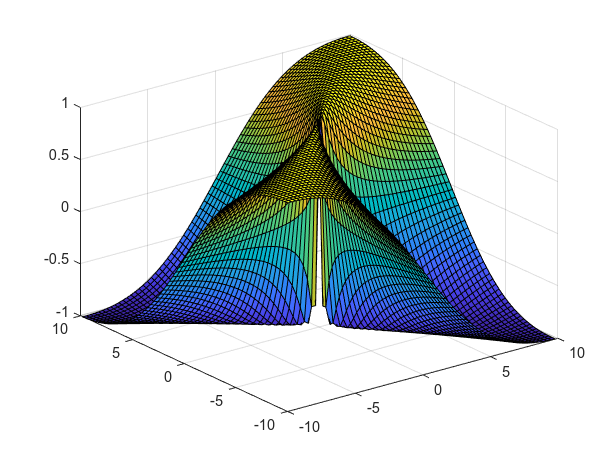

[x,y] = meshgrid(-10:0.3:10,-10:0.3:10);
z=2*x.*y./(x.^2+y.^2);
surf(x,y,z)

syms x y
f(x,y) = 2*x*y/(x^2 + y^2)

$$f(x, y) = \frac{2\,x\,y}{x^{2}+y^{2}}$$

Parece que en **(0,0)** hay problemas de representación. Así se ve también al sustituir mentalmente en la función.

### Continuidad. Límites.

limit(limit(f(x,y),x,0),y,0)

$$ans = 0$$

limit(limit(f(x,y),y,0),x,0)

$$ans = 0$$

Salen igual, comprobamos en haces de rectas, parábolas...

syms m

En haz de rectas `y = mx`

limit(f(x,m*x),x,0) 

$$ans = \frac{2\,m}{m^{2}+1}$$

Sale el límite dependiente de `m`. El límite no existe, por lo que la función no es continua ni diferenciable en **(0,0). **Si se elimina ese punto, la función es continua y diferenciable.

### Derivadas parciales.

f = 2*x*y/(x^2 + y^2)

$$f = \frac{2\,x\,y}{x^{2}+y^{2}}$$

f1x = diff(f,x,1)

$$f1x = \frac{2\,y}{x^{2}+y^{2}}-\frac{4\,x^{2}\,y}{{\left(x^{2}+y^{2}\right)}^{2}}$$

f1y = diff(f,y,1)

$$f1y = \frac{2\,x}{x^{2}+y^{2}}-\frac{4\,x\,y^{2}}{{\left(x^{2}+y^{2}\right)}^{2}}$$

f2xy = diff(f1x,y)

$$f2xy = \frac{2}{x^{2}+y^{2}}-\frac{4\,x^{2}}{{\left(x^{2}+y^{2}\right)}^{2}}-\frac{4\,y^{2}}{{\left(x^{2}+y^{2}\right)}^{2}}+\frac{16\,x^{2}\,y^{2}}{{\left(x^{2}+y^{2}\right)}^{3}}$$

f2yx = diff(f1y,x)

$$f2yx = \frac{2}{x^{2}+y^{2}}-\frac{4\,x^{2}}{{\left(x^{2}+y^{2}\right)}^{2}}-\frac{4\,y^{2}}{{\left(x^{2}+y^{2}\right)}^{2}}+\frac{16\,x^{2}\,y^{2}}{{\left(x^{2}+y^{2}\right)}^{3}}$$

f2x = diff(f,x,2)

$$f2x = \frac{16\,x^{3}\,y}{{\left(x^{2}+y^{2}\right)}^{3}}-\frac{12\,x\,y}{{\left(x^{2}+y^{2}\right)}^{2}}$$

f2y = diff(f,y,2)

$$f2y = \frac{16\,x\,y^{3}}{{\left(x^{2}+y^{2}\right)}^{3}}-\frac{12\,x\,y}{{\left(x^{2}+y^{2}\right)}^{2}}$$

#### Matrices Jacobiana y Hessiana.

jacobiana = jacobian(f)

$$jacobiana = \left(\begin{array}{cc} \frac{2\,y}{x^{2}+y^{2}}-\frac{4\,x^{2}\,y}{{\left(x^{2}+y^{2}\right)}^{2}} & \frac{2\,x}{x^{2}+y^{2}}-\frac{4\,x\,y^{2}}{{\left(x^{2}+y^{2}\right)}^{2}} \end{array}\right)$$

hessiana = hessian(f)

$$hessiana = \begin{array}{l} \left(\begin{array}{cc} \frac{16\,x^{3}\,y}{{\left(x^{2}+y^{2}\right)}^{3}}-\frac{12\,x\,y}{{\left(x^{2}+y^{2}\right)}^{2}} & \sigma_{1}\\ \sigma_{1} & \frac{16\,x\,y^{3}}{{\left(x^{2}+y^{2}\right)}^{3}}-\frac{12\,x\,y}{{\left(x^{2}+y^{2}\right)}^{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2}{x^{2}+y^{2}}-\frac{4\,x^{2}}{{\left(x^{2}+y^{2}\right)}^{2}}-\frac{4\,y^{2}}{{\left(x^{2}+y^{2}\right)}^{2}}+\frac{16\,x^{2}\,y^{2}}{{\left(x^{2}+y^{2}\right)}^{3}} \end{array}$$

Comparando los elementos de las matrices con los resultados de las derivadas escritos anteriormente se puede observar que son iguales, por lo que comprobamos que son correctos.